# Løsning på lortet

## Opgave 1

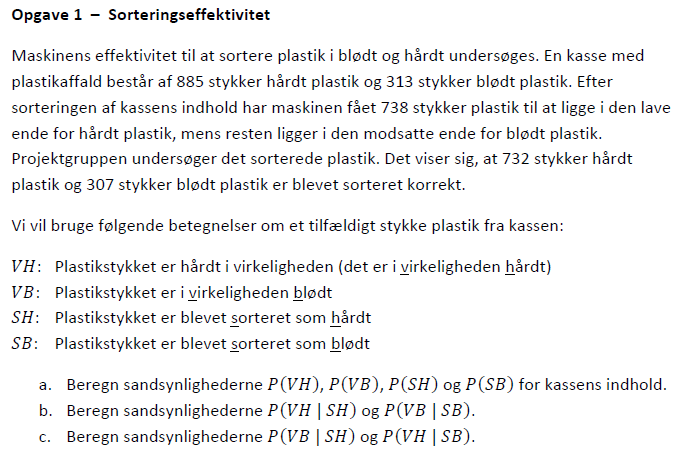

clc; clear all;

% Faktiske data
n_hard = 885; % Antal hårde plast stykker
n_soft = 313; % Antal bløde plast stykker
n_tot = n_hard + n_soft; % Total population af plast

% Maskinens sortering
m_hard = 738;              % Maskinen har sorteret så mange hårde
m_soft = n_tot - m_hard   % Maskinen har sorteret så mange bløde

m_soft = 460


% Antal der er sorteret korrekt
k_hard = 732;
k_soft = 307;

%---------------- Udregninger ----------------%

% Sandsynligheder til a)
pVH = n_hard/n_tot        % Hvor mange der faktisk er hårde, over hvor mange der er sorteret som hårde

pVH = 0.7387

pVB = n_soft/n_tot        % Hvor mange der faktisk er bløde, over hvor mange der er sorteret som bløde

pVB = 0.2613


pSH = m_hard/n_tot        % Hvor mange der er sorteret som hårde, ud fra den totale population

pSH = 0.6160

pSB = m_soft/n_tot        % Hvor mange der er sorteret som bløde, ud fra den totale population

pSB = 0.3840


% Sandsynligheder til b)
pVH_SH = k_hard/m_hard    % Hvor mange der faktisk er hårde, ift hvor mange der er sorteet som hårde

pVH_SH = 0.9919

pVB_SB = k_soft/m_soft    % Hvor mange der faktisk er bløde, ift hvor mange der er sorteet som bløde

pVB_SB = 0.6674


% Sandsynligheder til c)
pVB_SH = 1 - pVH_SH       % I virkeligheden blødt, men sorteret som hårdt

pVB_SH = 0.0081

pVH_SB = 1 - pVB_SB       % I virkeligheden hårdt, men sorteret som blødt

pVH_SB = 0.3326

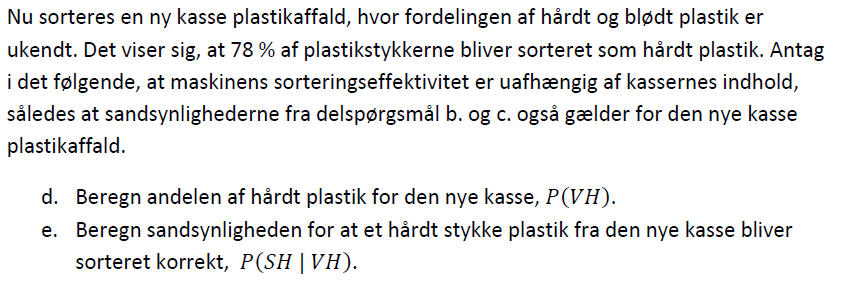

### Loven om total ssh

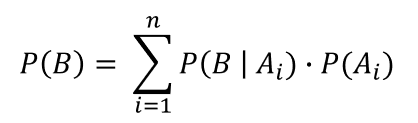

% Opgave d
pSH_ny = 0.78

pSH_ny = 0.7800

pSB_ny = 1 - pSH_ny

pSB_ny = 0.2200


% Sandsynligheden for at det i virkeligheden er hårdt ganget med ssh'en sorteret
% som hårdt, plus sandsynligheden for det i virkeligheden er hårdt, men
% sorteret som blødt ganget med ssh'en for sorteret som blødt
pVH_ny = pVH_SH * pSH_ny + pVH_SB * pSB_ny

pVH_ny = 0.8468


% Opgave e
% Bayes regel
pSH_VH = pVH_SH * pSH_ny/pVH_ny

pSH_VH = 0.9136

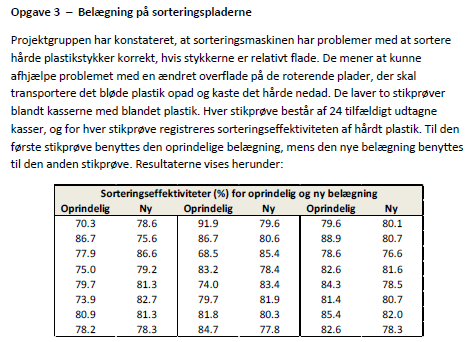

clc; clear;

data = importdata("Data_M4STI1_2019F.xlsx");
data = data.data(:,5:6)'

data =    70.3000   86.7000   77.9000   75.0000   79.7000   73.9000   80.9000   78.2000   91.9000   86.7000   68.5000   83.2000   74.0000   79.7000   81.8000   84.7000   79.6000   88.9000   78.6000   82.6000   84.3000   81.4000   85.4000   82.6000
   78.6000   75.6000   86.6000   79.2000   81.3000   82.7000   81.3000   78.3000   79.6000   80.6000   85.4000   78.4000   83.4000   81.9000   80.3000   77.8000   80.1000   80.7000   76.6000   81.6000   78.5000   80.7000   82.0000   78.3000


names = ["Oprindelig","Ny"];

deskripts(data,names)

      Datanavn      Middelværdi    Varians    Standardafvigelse    Målepunkter
    ____________    ___________    _______    _________________    ___________

    "Oprindelig"      80.688       31.881          5.6463              24     
    "Ny"              80.396       6.6048            2.57              24     



Da populations-standardafvigelsen er ukendt, følger stikprøvenStudents-t fordeling, med n-1 frihedsgrader, hvor n er antal værdier i stikprøven
Stikprøvestandardafvigelsen beregnes


$$s=\sqrt{\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}}$$

t-værdien findes


$$\frac{t_{\mathrm{df},\alpha }}{2}=-\mathrm{tinv}\,\left(\frac{\alpha }{2}\,n-1\right)$$

Øvre konfidensinterval værdi


$$\bar{y}+\frac{\frac{t_{\mathrm{df},\alpha }}{2}\,s}{\sqrt{n}}$$

Nedre konfidensinterval værdi


$$\bar{y}-\frac{\frac{t_{\mathrm{df},\alpha }}{2}\,s}{\sqrt{n}}$$

    Interval    Værdier    Test type    Testværdier     Værdi     Deskriptorer
    ________    _______    _________    ___________    _______    ____________

    "Nedre"     78.303     "t nedre"      -2.0687      "y_bar"       80.688   
    "Øvre"      83.072     "t øvre"        2.0687      "s"           5.6463   



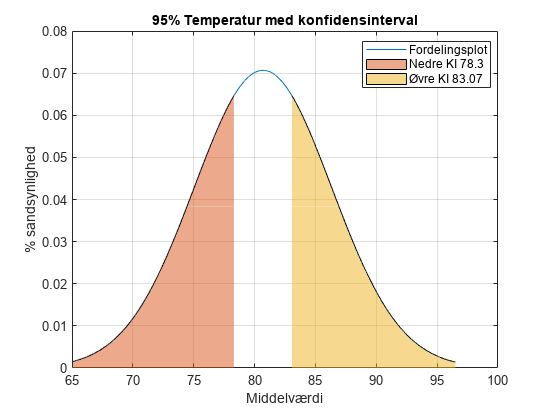

KI_op = struct with fields:
            KI: [2×1 double]
    test_alpha: [2×1 double]


% Oprindelig
Oprindelig = data(1,:);

KI_op = KonfidensIntervalNormal(Oprindelig, 95, [], 80.6875)

Da populations-standardafvigelsen er ukendt, følger stikprøvenStudents-t fordeling, med n-1 frihedsgrader, hvor n er antal værdier i stikprøven
Stikprøvestandardafvigelsen beregnes


$$s=\sqrt{\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}}$$

t-værdien findes


$$\frac{t_{\mathrm{df},\alpha }}{2}=-\mathrm{tinv}\,\left(\frac{\alpha }{2}\,n-1\right)$$

Øvre konfidensinterval værdi


$$\bar{y}+\frac{\frac{t_{\mathrm{df},\alpha }}{2}\,s}{\sqrt{n}}$$

Nedre konfidensinterval værdi


$$\bar{y}-\frac{\frac{t_{\mathrm{df},\alpha }}{2}\,s}{\sqrt{n}}$$

    Interval    Værdier    Test type    Testværdier     Værdi     Deskriptorer
    ________    _______    _________    ___________    _______    ____________

    "Nedre"     79.311     "t nedre"      -2.0687      "y_bar"       80.396   
    "Øvre"      81.481     "t øvre"        2.0687      "s"             2.57   



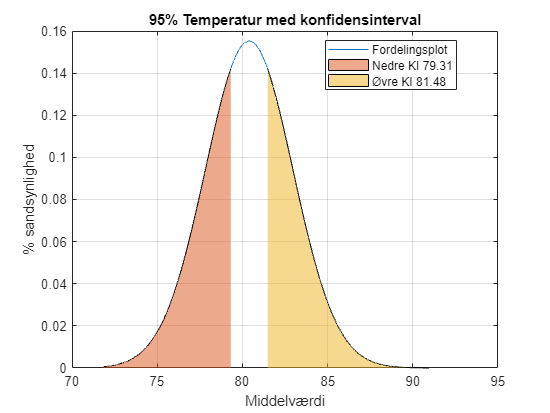

KI_ny = struct with fields:
            KI: [2×1 double]
    test_alpha: [2×1 double]


% Konfidensinterval ny
KI_ny = KonfidensIntervalNormal(data(2,:), 95, [], 80.396)

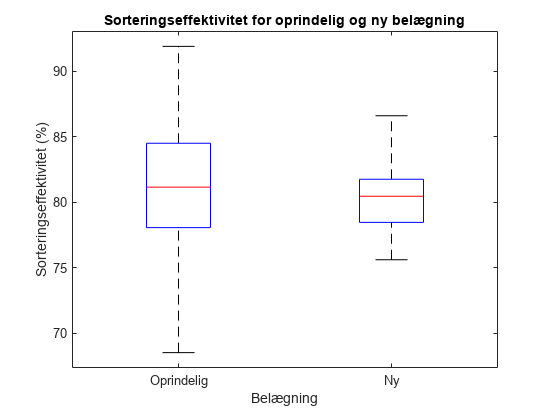


boxplot(data', 'Labels', {'Oprindelig', 'Ny'})
title('Sorteringseffektivitet for oprindelig og ny belægning')
ylabel('Sorteringseffektivitet (%)')
xlabel('Belægning')

Jamen, hypoterserne kommer til at se sådan her ud

Ho: var1 = var2

Ha: var1 =/= var2

Teststørrelsens værdi


$$F_{0}=\frac{{s_{1}}^{2}}{{s_{2}}^{2}}$$

-----------------------------------------------------------------
t-værdiens formel


$$\frac{F\,\alpha }{2}\,\mathrm{nedre}=\mathrm{finv}\,\frac{\alpha }{2}\,\mathrm{df}$$

$$\frac{F\,\alpha }{2}\,\mathrm{oevre}=\mathrm{finv}\,\left(1-\frac{\alpha }{2}\,\mathrm{df}\right)$$

-----------------------------------------------------------------
    Signifikansniveau    Nedre grænse    Øvre grænse    Teststatistik
    _________________    ____________    ___________    _____________

          0.05             0.43259         2.3116           4.827    



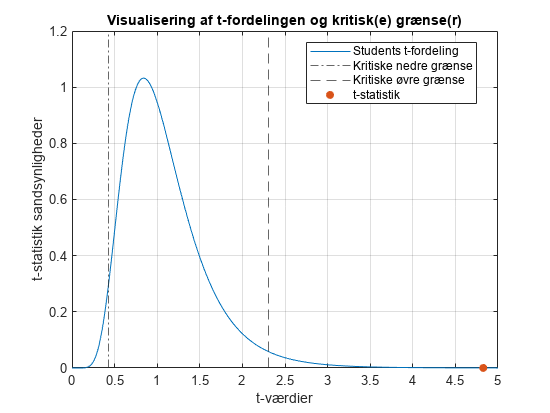

Da h = 1 forkastes nulhypotesen
Ydermere ses det også at t-værdien 4.827 overstiger den kritiske grænse på 2.3116


ans = struct with fields:
    stats: [1×1 struct]
        p: 3.6230e-04
       ci: [1.8438 12.6370]


VarTest2pop(data(1,:), data(2,:),"both",95,[])

På 5% signifikansniveau er der forskel på varianserne